# EXERCISE #3 Use the Simplest WLAN Network to Study QoS and Interference

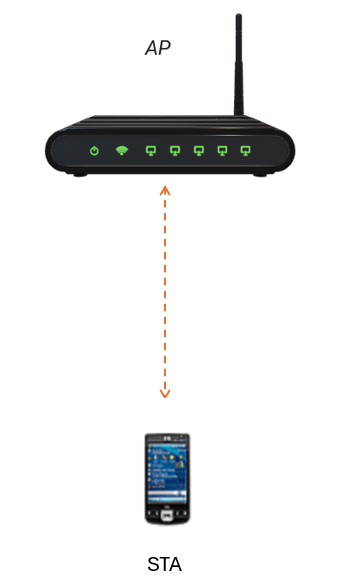

WLAN Network with one AP and one STA 

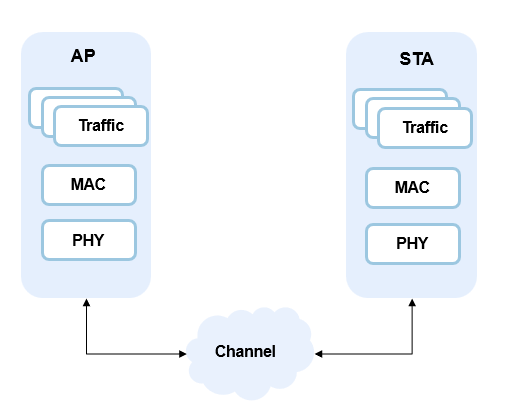

Modeled Blocks 

#### In this exercise, You will learn how to  

- Configure and create WLAN nodes and network

- Add custom application traffic to the nodes in the network

- Analyze WLAN network performance under Bluetooth interference

- Perform cleanup by closing previously opened windows and figures. 

clear all;
all_figs = findall(0, 'type', 'figure');close(all_figs);

- Initialize the random number generator for reproducibility

- Set the simulation time

- Initialize the network simulator

- Launch the wireless network viewer to visualize the network during simulation

- Define AP and STA position 

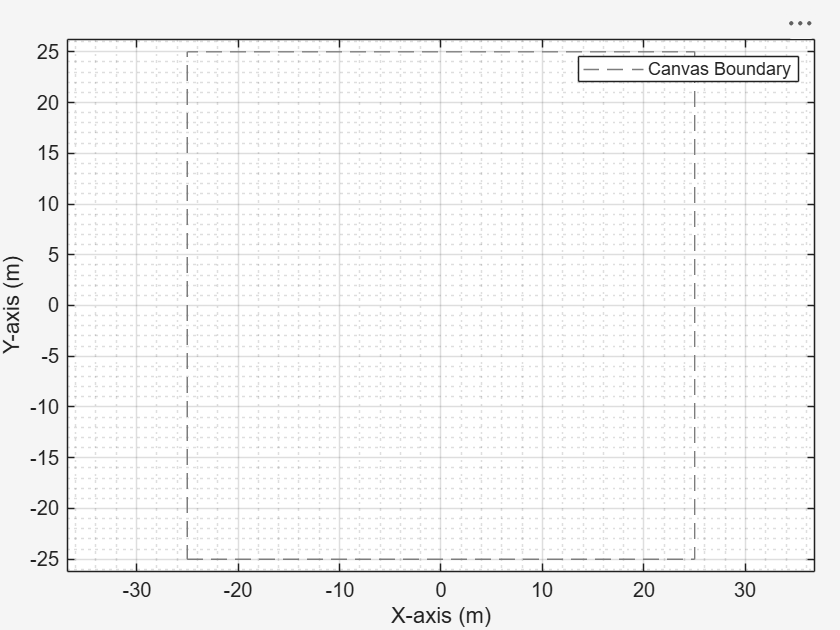

rng(1,"twister");
TU              = 1024e-6; 
simulationTime  = 100*TU;  
networkSimulator = wirelessNetworkSimulator.init;
networkViewerObj = wirelessNetworkViewer(CanvasSize=[50 50 0]);

AP_pos  = [0,0,0];
STA_pos = [5,5,0];

#### Select Interference Modeling Options

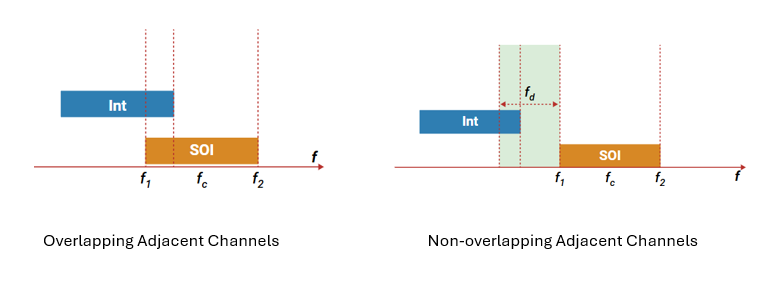

interferenceModeling = "overlapping-adjacent-channel";  
maxInterferenceOffset = 0;

#### QoS Parameters

Define Enhanced Distributed Channel Access (EDCA) parameters for the four Access Categories (ACs): Best Effort, Background, Video, and Voice.

- Specify **Arbitrary Interframe Space (AIFS)** values for each AC, in slot times (1 slot = 9 µs). 

- Specify **Minimum Contention Window (CWmin)** values for each AC, in slot counts. 

- Specify **Maximum Contention Window (CWmax)** values for each AC, in slot counts. 

- Specify **Transmission Opportunity (TXOP)** duration limits for each AC, in units of 32 microseconds.

aifs = [4 7 3 2];
cwMin = [15 15 7 3];
cwMax = [1023 1023 15 7];
txopLimit = [1 2 4 8];

#### Configure WLAN AP

band        = 2.4;
channel     = 7;
bandwidth   = 20e6;

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat", "HE-SU", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "InterferenceModeling",interferenceModeling, ...
    "MaxInterferenceOffset",maxInterferenceOffset, ...
    "CWMax",cwMax, ...
    "CWMin",cwMin, ...
    "AIFS",aifs, ...
    "TXOPLimit",txopLimit);

#### Create a WLAN Access Point (AP)

macmodel = "full-mac";
phymodel = "full-phy";

Note: All nodes on the network must have same MAC and PHY abstractions  

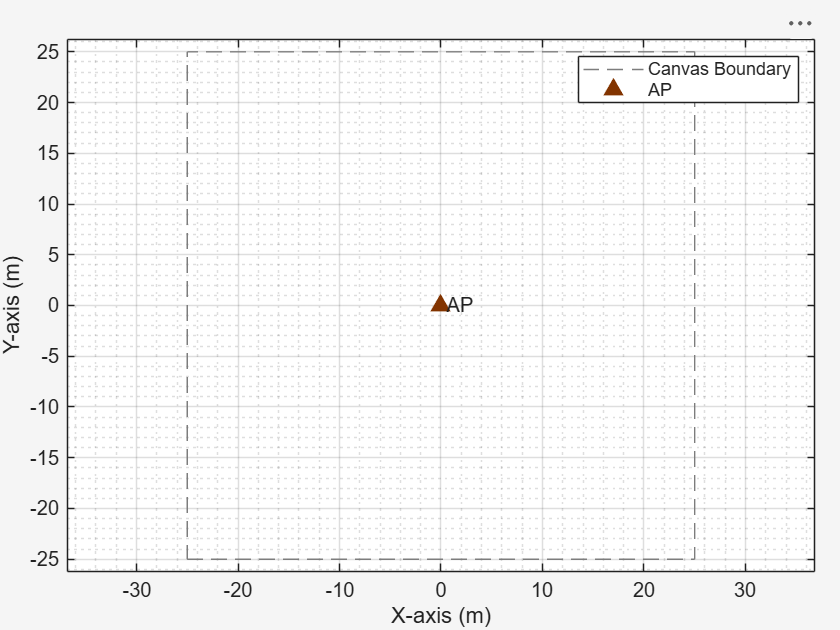

AP = wlanNode(...
    "Name","AP",...
    "Position",AP_pos, ...
    "DeviceConfig",APCfg,...    
   "MACModel",macmodel, ...
    "PHYModel",phymodel); 
addNodes(networkViewerObj,AP,Type="AP");

#### Create a WLAN Station (STA) and set up the BSS

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HE-SU", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "InterferenceModeling",interferenceModeling, ...
    "MaxInterferenceOffset",maxInterferenceOffset);

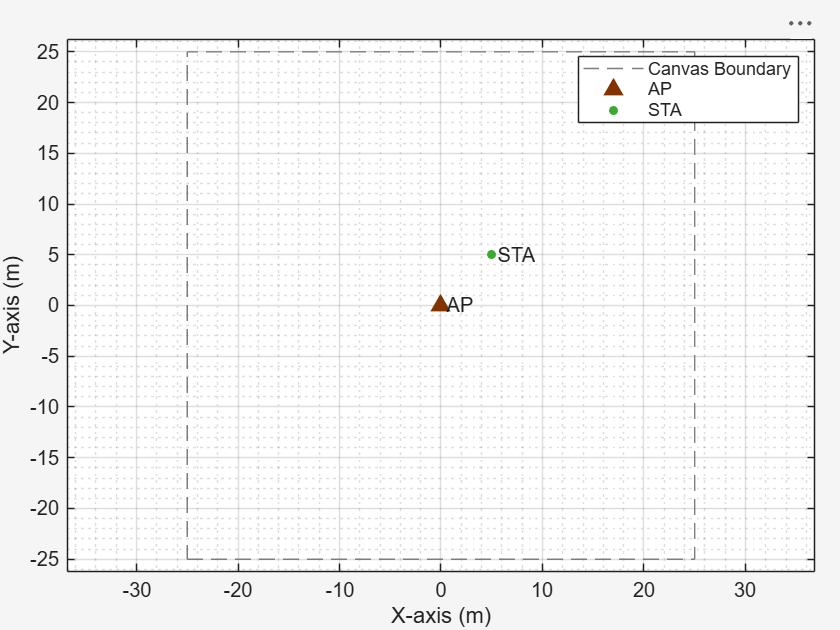

STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
     "MACModel",macmodel, ...
    "PHYModel",phymodel);
addNodes(networkViewerObj,STA,Type="STA");

#### Create the network 

associateStations(AP,STA);

# Task #1/4 Configure a traffic model 

**Description of the Task** 

#### 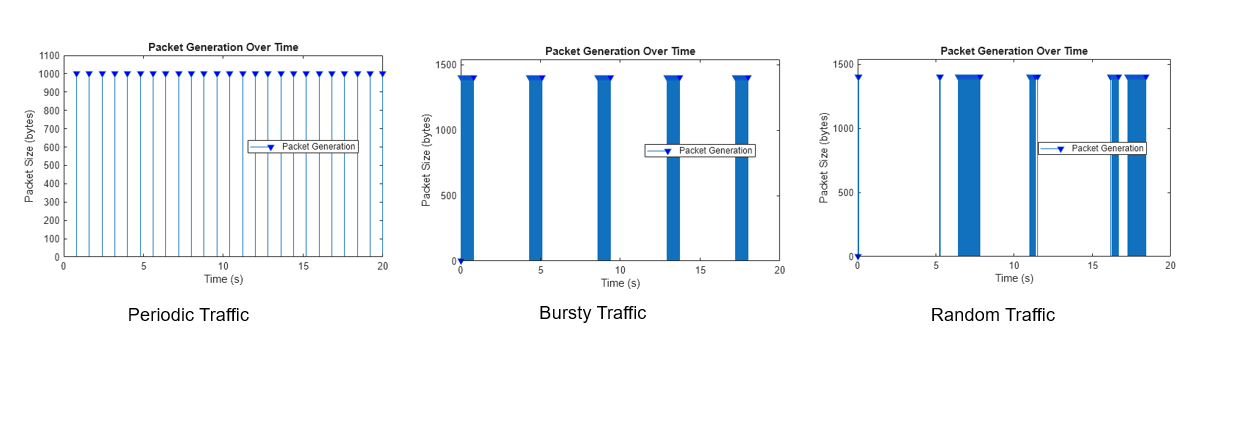

**Instructions to complete the task**

Use networkTrafficOnOff() function to configure QoS Traffic

Write configuration in a variable named "trafficCfg"

Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

-     "OnTime", simulationTime

-     "OffTime", 0

-     "DataRate",dataRate

-     "PacketSize",packetSize

dataRate = 2000; % In kpbs
packetSize = 512; % In Bytes

% <enter code below>
trafficCfg = networkTrafficOnOff(...
    "OnTime", simulationTime,...
    "OffTime", 0, ...
    "DataRate",dataRate, ...
    "PacketSize",packetSize);

Time: 0.000000 s - Generated a periodic packet of size 512 bytes
Time: 0.002048 s - Generated a periodic packet of size 512 bytes
Time: 0.004096 s - Generated a periodic packet of size 512 bytes
Time: 0.006144 s - Generated a periodic packet of size 512 bytes
Time: 0.008192 s - Generated a periodic packet of size 512 bytes
Time: 0.010240 s - Generated a periodic packet of size 512 bytes
Time: 0.012288 s - Generated a periodic packet of size 512 bytes
Time: 0.014336 s - Generated a periodic packet of size 512 bytes
Time: 0.016384 s - Generated a periodic packet of size 512 bytes
Time: 0.018432 s - Generated a periodic packet of size 512 bytes
Time: 0.020480 s - Generated a periodic packet of size 512 bytes
Time: 0.022528 s - Generated a periodic packet of size 512 bytes
Time: 0.024576 s - Generated a periodic packet of size 512 bytes
Time: 0.026624 s - Generated a periodic packet of size 512 bytes
Time: 0.028672 s - Generated a periodic packet of size 512 bytes
Time: 0.030720 s - Genera

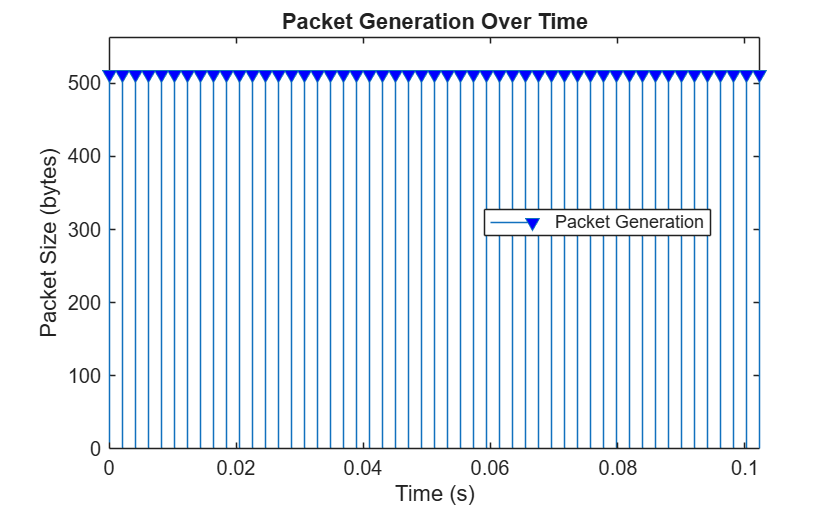

plotTrafficPattern(simulationTime,trafficCfg);

# Task #2/4 Integrate a traffic model into AP with "AccessCategory",2

#### **Description of the Task**

**Instructions to complete the task**

Add traffic from source to destination

Use addTrafficSource() function to add the traffic to simulation

Hint: Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

- AP

- trafficCfg

- "DestinationNode",STA

- "AccessCategory",2

% <enter code below>
addTrafficSource(AP, ...
    trafficCfg, ...
    "DestinationNode", STA, ...
    "AccessCategory",2);

# Task #3/4 Integrate a traffic model into AP with "AccessCategory",3

**Instructions to complete the task**

Add traffic from source to destination

Use addTrafficSource() function to add the traffic to simulation

Hint: Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

- AP

- trafficCfg

- "DestinationNode",STA

- "AccessCategory",3

addTrafficSource(AP, ...
    trafficCfg, ...
    "DestinationNode",STA, ...
    "AccessCategory",3)

#### Introduce **Bluetooth interference** into the simulation to study coexistence effects

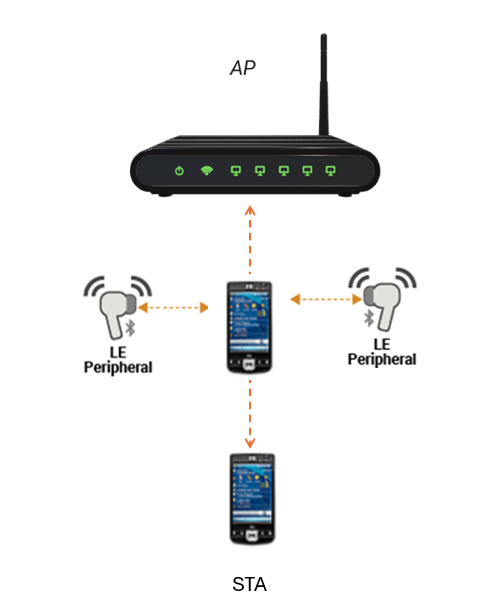

enableBluetoothLEInterference = true;
if enableBluetoothLEInterference
    source = bluetoothLENode("central","Name","bt",Position=[2,0,0],TransmitterPower=0, TransmitterGain=0,ReceiverGain=0,ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling,MaxInterferenceOffset=maxInterferenceOffset);
    leftSink = bluetoothLENode("Peripheral", Position=[5,3,0],Name="bt",TransmitterPower=0, TransmitterGain=0, ReceiverGain=0,ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling,MaxInterferenceOffset=maxInterferenceOffset);
    rightSink = bluetoothLENode("Peripheral", Position=[3,3,0],Name="bt",TransmitterPower=0,TransmitterGain=0,ReceiverGain=0, ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling);
    cfgCIS = bluetoothLECISConfig(ISOInterval=0.050,NumSubevents=9,BurstNumber=9,SubInterval= 2.5e-3,MaxPDU= 251,FlushTimeout= 1,TMSS= 150e-6,TIFS= 150e-6);
    cfgConnection = bluetoothLEConnectionConfig(ConnectionInterval=0.1,ActivePeriod=0.001,MaxPDU=27,PHYMode="LE2M");
    cfgConnection.AccessAddress = "5DA44270"; cfgConnection.ConnectionOffset = 0; [leftConnCfg,leftCISCfg] = configureConnection(cfgConnection,source,leftSink,CISConfig=cfgCIS);
    cfgConnection.AccessAddress = "5DA44271"; cfgConnection.ConnectionOffset = 0.05; [rightConnCfg,rightCISCfg] = configureConnection(cfgConnection,source,rightSink,CISConfig=cfgCIS);
    traffic = networkTrafficOnOff(DataRate=320,PacketSize=cfgCIS.MaxPDU,OnTime=simulationTime,OffTime=0);
    addTrafficSource(source,traffic,DestinationNode=leftSink,CISConfig=leftCISCfg);
    addTrafficSource(source,traffic,DestinationNode=rightSink,CISConfig=rightCISCfg);
    intBluetoothLENodes = [source leftSink rightSink];
end

#### **Add Bluetooth nodes to the network simulator **

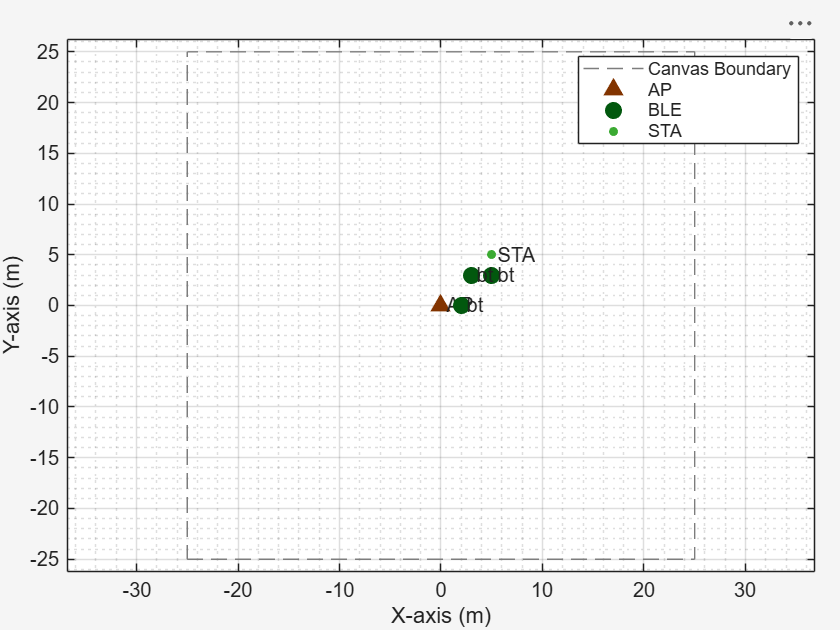

wlanNodes = [AP, STA];
addNodes(networkSimulator,wlanNodes)
if enableBluetoothLEInterference 
    addNodes(networkSimulator,intBluetoothLENodes);
    addNodes(networkViewerObj,intBluetoothLENodes,Type="BLE");
end

nodes = networkSimulator.Nodes;

#### Add channel model to the simulator

This channel is based on TGax simulation scenarios document (doc.: IEEE 802.11-14/0980r16). It models NLOS, Model-D delay profile, freespace pathloss based off of doc.: IEEE 802.11-14/0980r16.

channelModel = false;
if channelModel
    channel = hSLSTGaxMultiFrequencySystemChannel(wlanNodes);
    addChannelModel(networkSimulator,channelFunction(channel))
end

**Enable PCAP capture**

The wlanPCAPWriter saves generated and received WLAN MAC packets to a PCAP or PCAPNG file.

capturePacketsObj =wlanPCAPWriter(Node=wlanNodes, RadiotapPresent=1);

#### Enable capture of IQ samples

Use the `wirelessIQLogger`  to log in-phase and quadrature (IQ) samples from wireless nodes in a wireless network simulation.

enableIQCapture = false;
if enableIQCapture
    iqSampleObj = wirelessIQLogger(wlanNodes);
end

#### Enable packet visualization

- Use the **wirelessTrafficViewer** object to monitor wireless nodes 

- View node state transitions over time 

- See channel occupancy for each node 

- Visualize packet transmissions over time 

viewerObj = wirelessTrafficViewer;
addNodes(viewerObj,nodes);

#### Enable node performance visualization 

perfViewerObj = helperPerformanceViewer(wlanNodes,simulationTime);

# Task 4/4: Run the simulation

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use addNodes() function to add Bluetooth LE nodes to the network simulator   

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

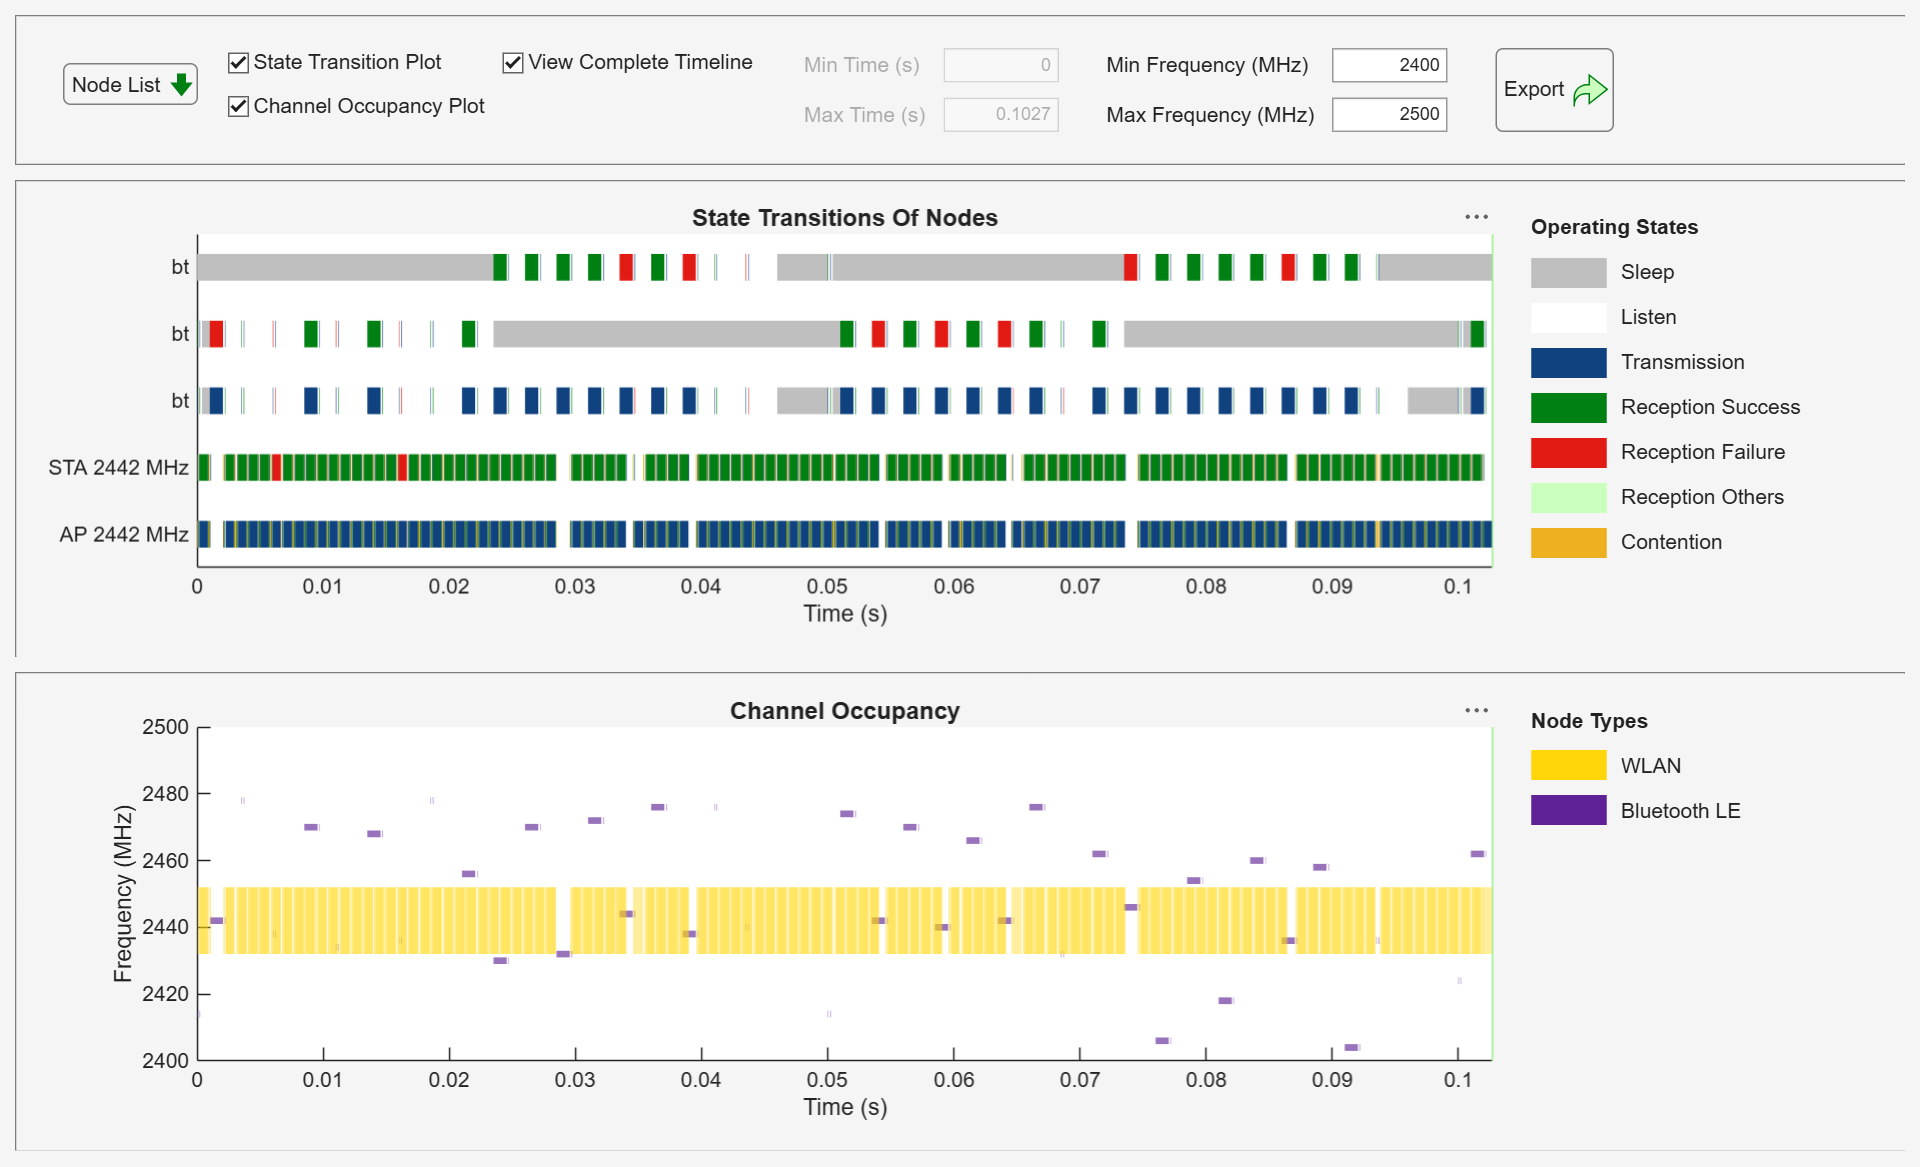

% <enter code below>
run (networkSimulator,simulationTime)

#### Print QoS Statistics 

APStatistics  = statistics(AP,"all");
[BestEffort, Background, Video,Voice ] = APStatistics.MAC.AccessCategories.TransmittedDataFrames

BestEffort = 0

Background = 0

Video = 51

Voice = 55

#### Plot node performance (Throughput , Packet Loss, and Latency) 

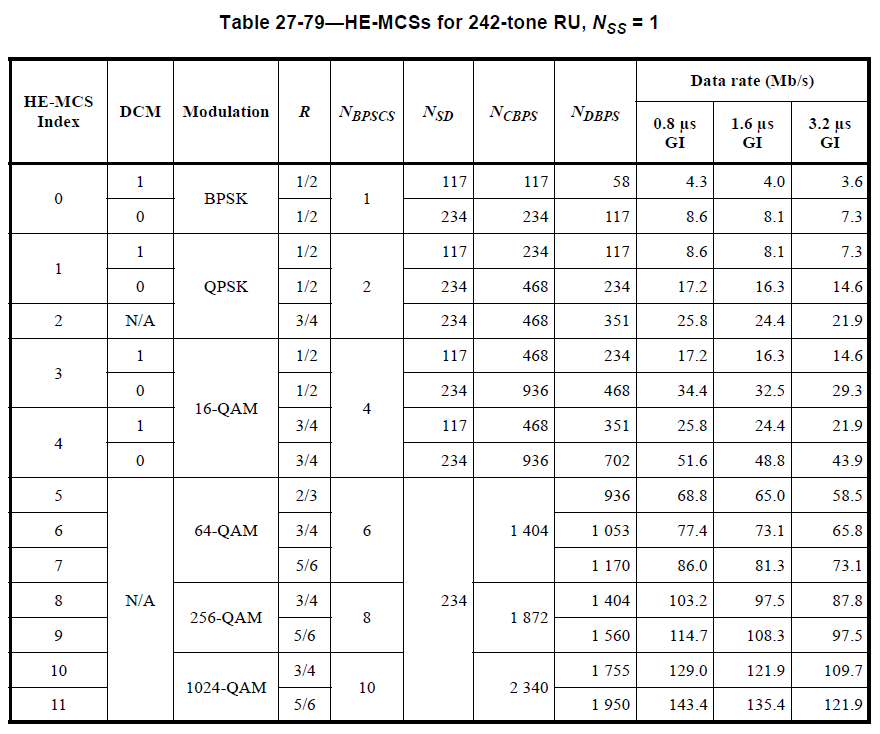

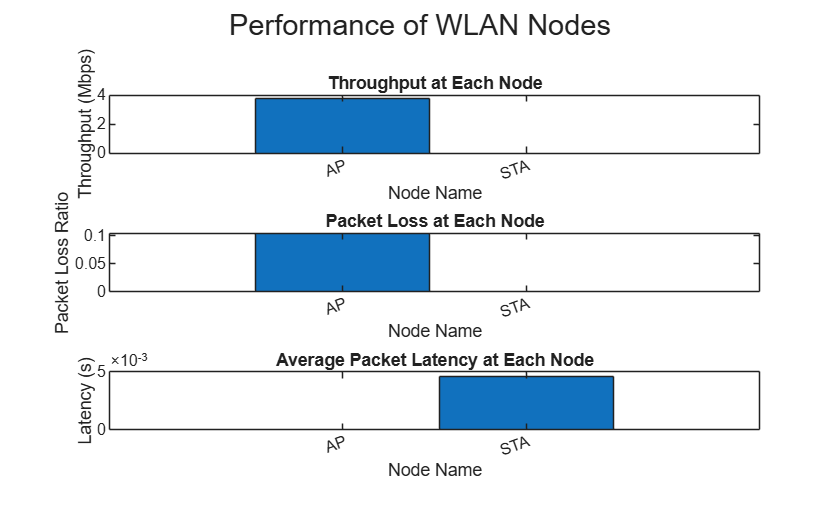

plotNetworkStats(perfViewerObj);

#### IQ sample visualization

enableIQVisualization = false; 
if enableIQVisualization
    fileName = iqSampleObj(1).FileName;
    iqData = load(fileName);
    signalAnalyzer(iqData.Waveform,SampleRate=iqData.Fs);
end
delete(capturePacketsObj);

Copyright 2025-2026 The MathWorks, Inc